alpha=1+mod(269,3);

## Problem 1

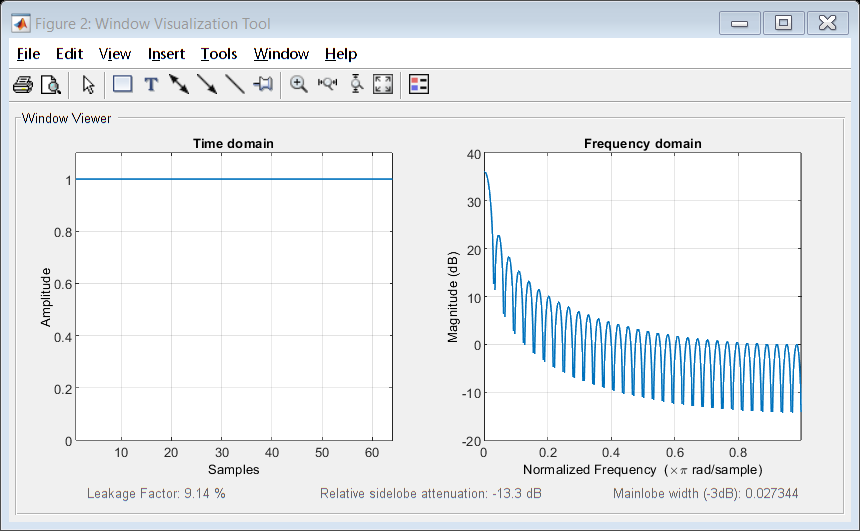

wvtool(rectwin(64))

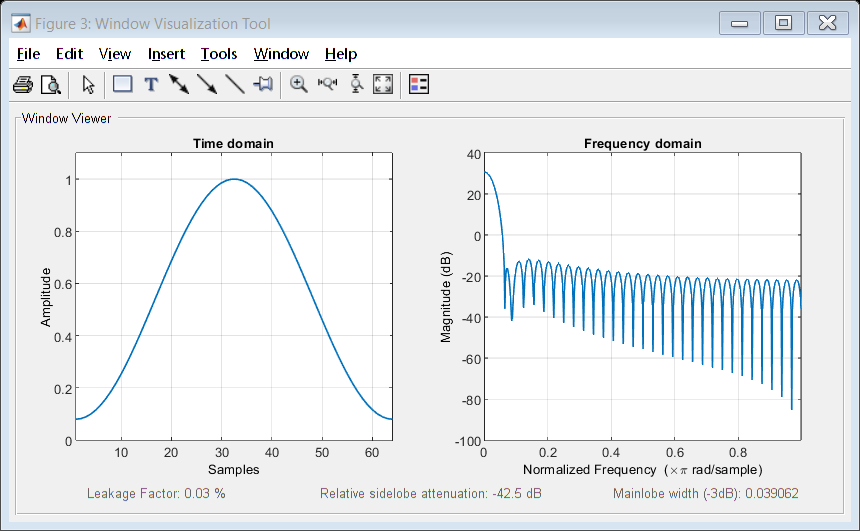

title("Rectangular Window")
wvtool(hamming(64))

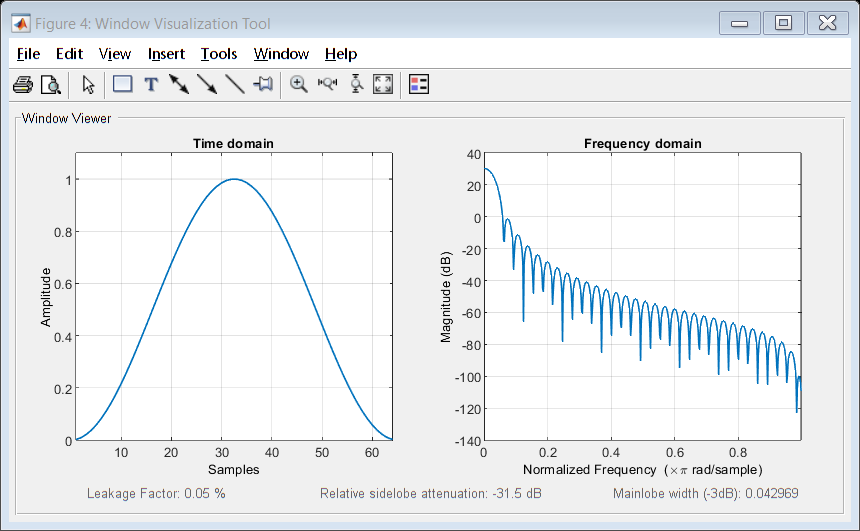

title("Hamming Window")
wvtool(hanning(64))

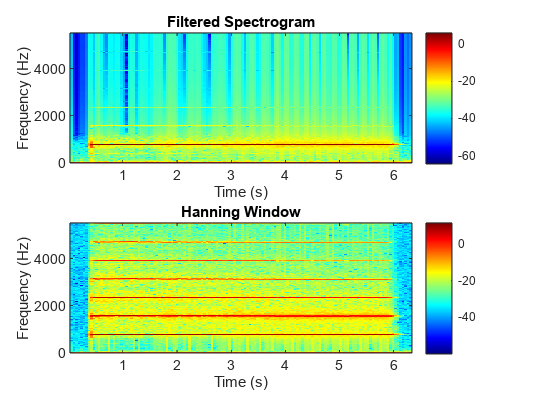

title("Hanning Window")

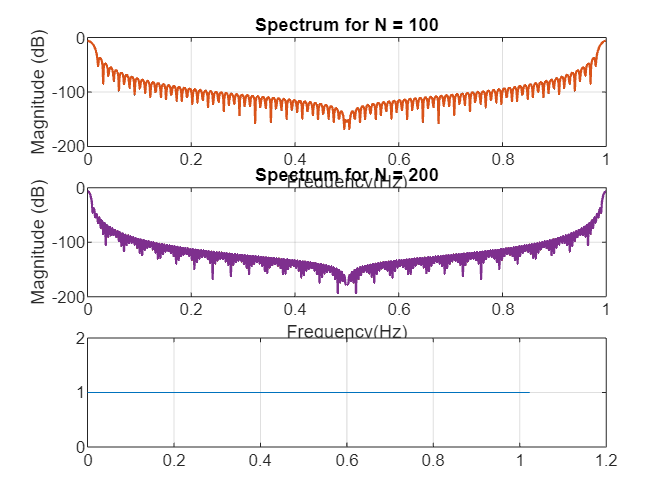

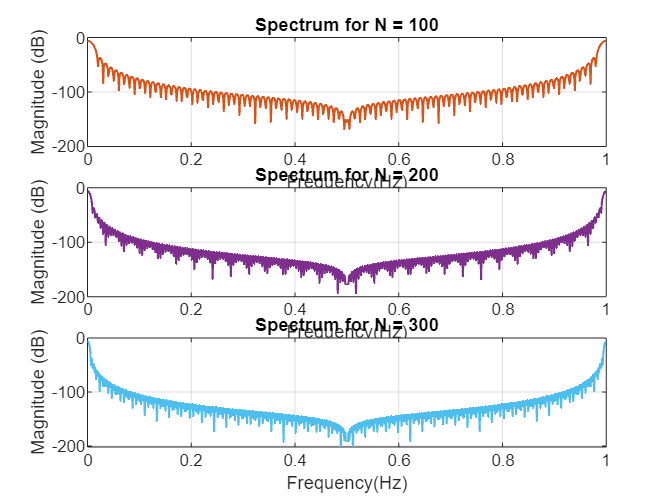

%Specify the parameters
N_values=[100,200,300];
DFT_size=1024;
fs=1000;        %Sampling rate
F=100;          %Signal Frequency
time=(0:(DFT_size-1))/fs;
%Define the signal and windowing
signal=ones(1,1024);
plot(time, signal);
grid on;
for i=1:length(N_values)
    window=hann(N_values(i));
    windowed_signal=window.*signal(1:N_values(i));

    %Compute the DFT
    signal_DFT=fft(windowed_signal, DFT_size);
    normalized=abs(signal_DFT)/N_values(i);

    %Make the frequency axis
    f=(0:(DFT_size-1))/DFT_size;

    %Plot the spectrum
    subplot(3,1,i);
    plot(f,20*log10(normalized), "LineWidth",1);
    grid on;
    title(sprintf("Spectrum for N = %d", N_values(i)));
    xlabel("Frequency(Hz)");
    ylabel("Magnitude (dB)");
end

## Problem 2

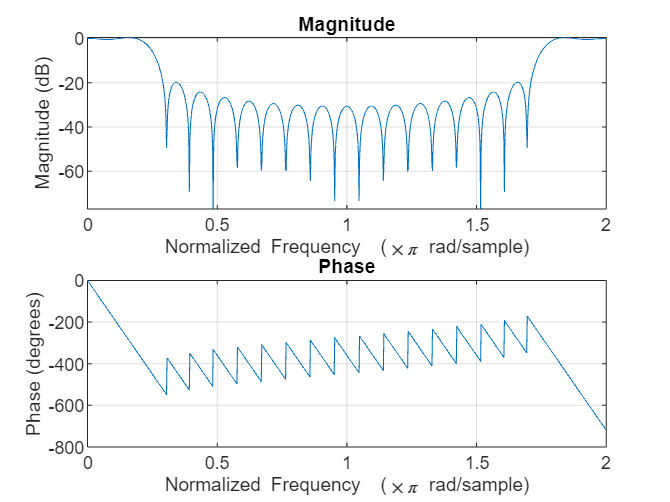

% Specify the parameters
f_cutoff=0.25;
L=21;

% Design the filters
Rect_filter=fir1(L-1, f_cutoff, "low", rectwin(L));     %Rectangular window
Hamm_filter=fir1(L-1,f_cutoff, "low", hamming(L));      %Hanning Window
freqz(Rect_filter, 1, 1024,"whole");

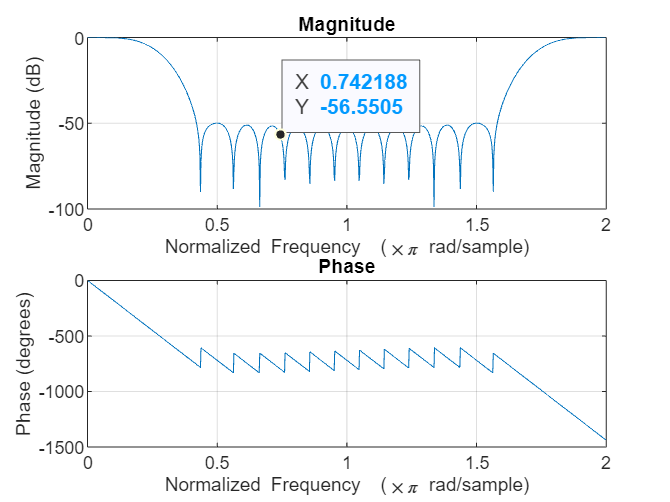

freqz(Hamm_filter, 1, 1024, "whole");

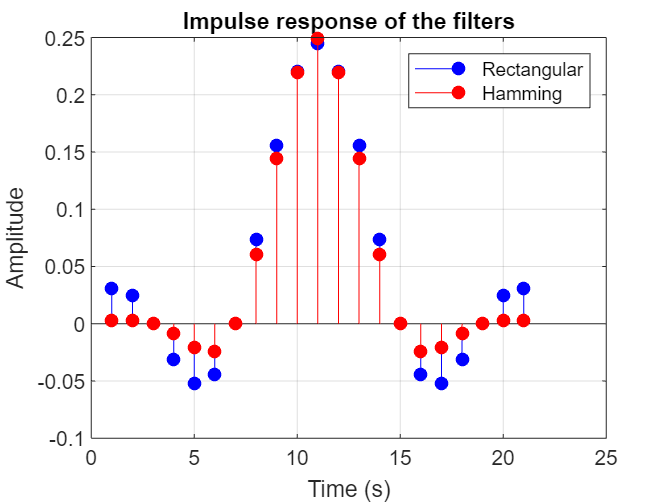


% Impulse responses of the filters
stem(Rect_filter,'b', "MarkerFaceColor","b");
hold on;
stem(Hamm_filter,'r', "MarkerFaceColor","r");
hold off;
grid on;
xlabel("Time (s)");
ylabel("Amplitude");
title("Impulse response of the filters");
legend("Rectangular", "Hamming");

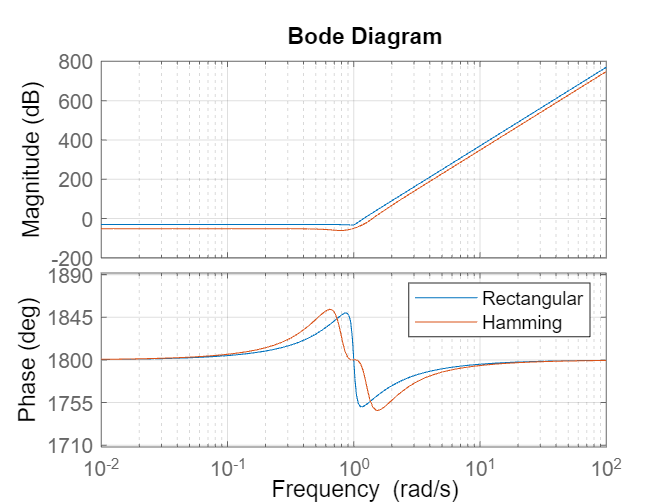


% Plot the bode plots
bode(tf(Rect_filter, 1),tf(Hamm_filter, 1));
grid on;
legend("Rectangular", "Hamming");

## Problem 2

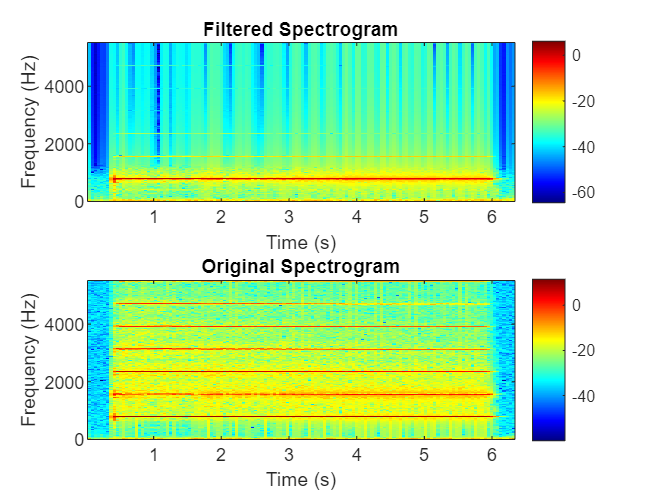

%Load the file and plot the spectrogram
[y, Fs]=audioread("instru3.wav");
[S,F,T]=spectrogram(y, hamming(1024), 512, [], Fs);

%Design a digital filter
L=31;
cutoff_f=1500;
[b,a]=fir1(L-1, cutoff_f/Fs, "bandpass", hamming(L));

%Filter the signal and plot the new spectrogram
new_signal=filter(b,a,y);
S_filtered=spectrogram(new_signal, hamming(1024), 512, [], Fs);

%Plot both the graphs
subplot(2,1,1);
imagesc(T, F, 10*log10(abs(S_filtered)));
axis xy;
colormap jet;
ylabel("Frequency (Hz)");
xlabel("Time (s)");
title("Filtered Spectrogram");
colorbar;
subplot(2,1,2);
imagesc(T, F, 10*log10(abs(S)))
axis xy
colormap jet;
title("Original Spectrogram");
ylabel("Frequency (Hz)");
xlabel("Time (s)");
colorbar;


%Save and listen to the file
audiowrite("filtered_output.wav", new_signal, Fs);
sound(new_signal, Fs);